# Phase Planes

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Getting started with the Phase Plane app

In this live script lesson, you will use the Phase Plane app to interactively analyze systems of two autonomous ODEs. Get started with the app by completing the following activity.

    **Activity. **

        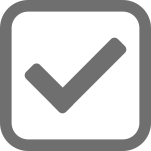  Visit the [GitHub repository](https://github.com/MathWorks-Teaching-Resources/Phase-Plane-and-Slope-Field) and watch the [Phase Plane app tutorial](https://user-images.githubusercontent.com/81383420/134724074-25ac1212-2aa7-429b-b93d-550667641cf7.mp4). You can find all the tutorial videos in the [GitHub readme](https://github.com/MathWorks-Teaching-Resources/Phase-Plane-and-Slope-Field#Getting-Started).

          Download the repository code which contains the app by clicking the **Code **button and selecting **Download ZIP**. Unzip the downloaded repository and open the folder containing the files inside MATLAB. 

         Open the Phase Plane app by right-clicking the app and selecting **run**. Generate a solution with initial values $x(0)=1$ and $y(0) = -1$ using the default equations. The solution curve should appear as shown in the figure below.

 The app requires a recent MATLAB release (the required release is stated in the GitHub repository). If you're running an older version of MATLAB, download the [latest version](https://www.mathworks.com/downloads/) of MATLAB or open the app in [MATLAB Online](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Phase-Plane-and-Slope-Field) instead.

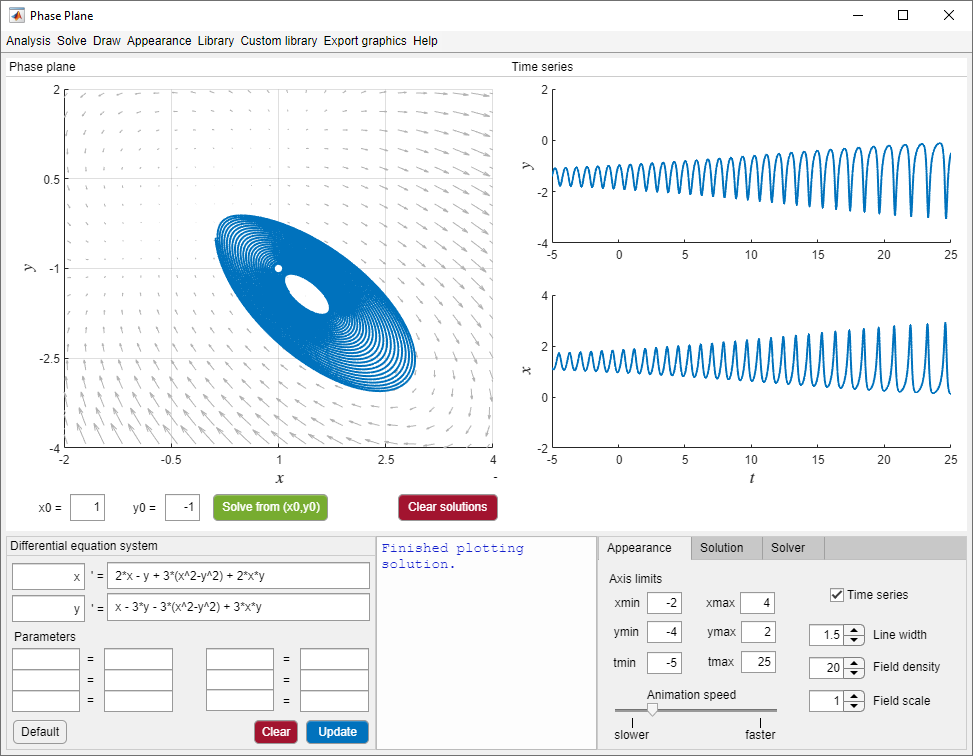

*A solution of the default ODE system*


$$\begin{array}{rl}
x' &=  2x - y + 3(x^2-y^2) + 2xy
\\
y' &=  x - 3y - 3(x^2-y^2) + 3xy
\end{array}$$


*with *$x(0)=1$ *and *$y(0) = -1$.

## Systems of ODEs

A system of differential equations is simply several ODEs written together. Typically, systems of ODEs are coupled, meaning that multiple variables will appear in each equation. The predator-prey (also known as the Lotka-Volterra) ODE system is a classic example:

    
$$\begin{array}{rl}
\frac{dx}{dt} &= ax - bxy
\\
\frac{dy}{dt} &=  -cy + dxy
\end{array}$$


These equations describe the evolution of interacting predator ($y$) and prey ($x$) populations. The predator-prey equations are nonlinear due to the $xy$ terms. In this lesson, you will learn to analyze the qualitative behavior of first order, autonomous systems of differential equations.

** Exercise. **Which of the following are systems of **autonomous**, **first order**, **linear** differential equations? 

**(1)** $y'' + y' -5 = 0$             **(2)** $\begin{array}{rl}
\frac{dx}{dt} &= ax - bxy
\\
\frac{dy}{dt} &=  -cy + dxy
\end{array}$         **(3)** $\begin{array}{rl}
x' &= v
\\
v' &=  -kx + cmv
\end{array}$        

**(4)** $\begin{array}{rl}
x' &= y
\\
y' &=  -y +3x + x^3
\end{array}$      **(5)** $\begin{array}{rl}
\frac{d \theta}{dt} &= \omega
\\
\frac{d\omega}{dt} &= -\sin \theta - d\omega
\end{array}$     **(6)**    $\begin{array}{rl}
x' &= a^2x - y
\\
y' &=  x
\end{array}$          

Note that $a$, $b$, $c$, $d$, $k$, and $m$ are constant parameters. Write your answer as a comma separated list (e.g., 1,4) in the space provided.

EquationList = [3,6]; 
CheckCriterionExercise(EquationList) % Checks your answer

Correct!


**  Reflect.** 

- Several of these equations model a physical system. Do you recognize any of them?

- Equation (1) is second order, but as you'll find later in this lesson, it can be written as a system of two first order equations. Can you find a definition for an additional variable $u$ that converts (1) into a system of two first order differential equations?

## The mass-spring-damper model

Vibrating systems are ubiquitous across engineering disciplines. The mass-spring-damper model provides a simple way to characterize a vibrating system.

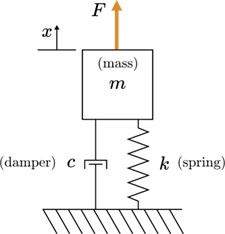

*Illustration of a mass-spring-damper model*

The variable $x$ is a function of time $t$ and represents the displacement of the mass from its resting position (in meters). The other parameters of the system are

- $k$: spring stiffness [N/m]

- $c$: damping coefficient [N$\cdot$s/m]

- $m$: mass [kg]

- $F$: externally applied force [N] 

**Derivation of the mass-spring-damper ODE**

Newton's 2nd law is applied to derive the equations of motion for the mass-spring-damper.


$$m x'' = \sum \text{Forces}

$$


Three forces act on the mass: 

- a restoring force from the spring: $-kx$

- a damping force: $-cx'$

- an external force $F$

Substituting these forces into Newton's 2nd law yields the 2nd order ODE:


$$m x'' = F - kx - c x'$$


### Writing second order ODEs as first order systems

Consider a general, second order autonomous ODE:


$$f(y,y',y'') = 0$$


This ODE may be written as a system of two first order ODEs by defining an auxiliary variable, $u = y'$. Substitute $u$ into the second order ODE and you now have two first-order equations:


$$\begin{array}{rl}
y' &= u
\\
f(y,u,u') &= 0
\end{array}$$


** Example. **Write the mass-spring-damper ODE as a system of two first-order differential equations.


$$m x'' = F - kx - c x'$$


**Solution.** Define the variable:


$$v = x'$$


The new variable is named $v$ because it represents the velocity of the mass. Substituting $v$ into the mass-spring-damper ODE yields the system:


$$\begin{array}{rl}

x' &= v
\\
mv' &=  F - kx - cv
\end{array}$$


Typically, the ODE system will be written with only the derivatives on the left-hand-side (LHS):


$$\begin{array}{rl}

x' &= v
\\
v' &= \frac{1}{m}( F - kx - cv)
\end{array}$$


** Exercise. **The equations of motion for a pendulum of length $l$ are found by applying Newton's 2nd law. The result is


$$\theta'' + \frac{g}{l} \sin \theta = 0$$


where $\theta$ is the angular displacement and $g$ is the acceleration due to gravity.

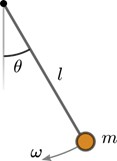

*Pendulum diagram*

**a.** Write the pendulum equations as a system of two first order differential equations. Use $\omega$ as your auxiliary variable (the angular velocity).

**Solution:**


$$\omega ' = -\frac{g}{l}\sin(\theta)$$



$$\theta' = \omega$$
            

**b. **Is the resulting system linear?

**Solution: **

No, the system is nonlinear because of the $\sin(\theta)$ term. 

ShowPendulumAnswer(true) % Click to show the answer

$$\mathrm{a. The system is}$$

$$\frac{d\,\theta }{d\,t}=\omega$$

$$\frac{d\,\omega }{d\,t}=\frac{-g}{l}\,\sin\left(\theta \right)$$

$$\mathrm{b. The system is nonlinear.}$$

## Phase planes

Systems of two autonomous, first order ODEs can be visually characterized by a **phase plane**. The ODE system itself is characterized by a vector field.

- The phase plane portrait plots the **dependent** variables against each other (the independent variable is not explicitly plotted). These are often called *state* variables.

- The direction of each vector field arrow is determined by evaluating the ODE derivatives.

- Solutions plotted in the phase plane will follow the field arrows.

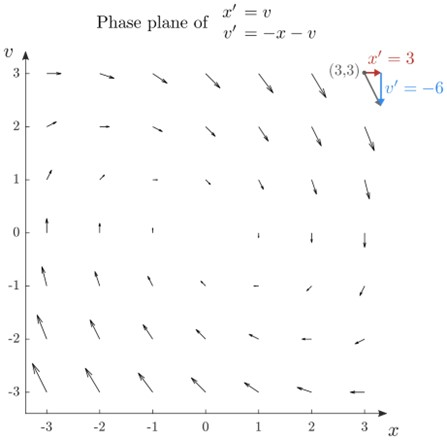

*Phase plane of the mass-spring-damper ODE system with *$m = k = c = 1$* and *$F = 0$*.*

Notice that:

- Each vector arrow has a slope that corresponds to the ratio of the derivatives: $v' / x'$.

- The independent variable $t$ is not explicitly represented in the phase plane.

### Creating a phase plane

You can create a phase plane vector field on paper by drawing the slopes at several points as the ratios of the derivatives. You can do the same thing in code by generating a mesh, evaluating the ODE functions, and plotting the result with arrows.

 **Example. **Generate a phase plane for the simple pendulum ODE system with $g = l = 1$:


$$\begin{array}{rl}

\theta' &= \omega
\\
\omega' &= -\sin \theta
\end{array}$$


**Solution. **To generate the phase plane, start by creating a mesh of points of the dependent variables using [`meshgrid`](https://www.mathworks.com/help/matlab/ref/meshgrid.html).

 
theta = 0:pi/4:4*pi; 
omega = -pi:pi/4:pi;
[thetaMesh,omegaMesh] = meshgrid(theta,omega); % create matrices THETA and OMEGA that are arrays of points through the plane
thetaMesh
omegaMesh

Then, evaluate the derivative functions: 

      
$$\begin{array}{rl}

f(\theta, \omega)&= \omega
\\
g(\theta, \omega) &= -\sin \theta
\end{array}$$


and use the [`quiver`](https://www.mathworks.com/help/matlab/ref/quiver.html) function to plot the vector field using arrows.

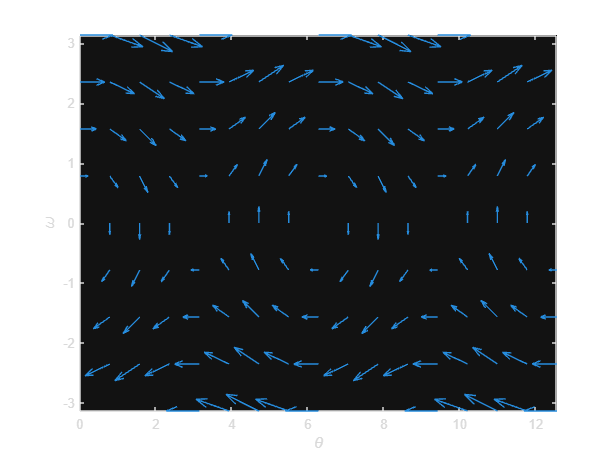

 
f = omegaMesh; % Evaluate f on the mesh
g = -sin(thetaMesh); % Evaluate g on the mesh
quiver(thetaMesh,omegaMesh,f,g) % Create the field arrows
axis([min(theta) max(theta) min(omega) max(omega)]) % Automatically scale the axes
xlabel("\theta")
ylabel("\omega")

    **Activity. **In this activity, you will use the Phase Plane app to generate phase plane vector fields, rather than writing code in MATLAB. Start by opening the Phase Plane app and then follow the instructions below.

**Task 1.** Set the ODE system to 

       
$$\begin{array}{rl}

\theta' &= \omega
\\
\omega' &= - \sin \theta
\end{array}$$


and adjust the axis limits so that they match the ones in the previous example. Does the phase plane vector field match the one shown in the previous example?

**Task 2. **Also, generate fields for the systems:

**a.**  $\begin{array}{rl}
x' &= v
\\
v' &=  - x - v
\end{array}$       **b.** $\begin{array}{rl}
x' &= \sin(y)
\\
y' &=  \sin(x)
\end{array}$        **c.** $\begin{array}{rl}
\frac{dx}{dt} &= x - xy
\\
\frac{dy}{dt} &=  -y + xy
\end{array}$  

If you find that it is difficult to see the field arrows, try adjusting the axis limits and selecting **Appearance > Field orientation only **from the drop-down menu.

 You need to use an asterisk (`*`) when writing multiplication in the ODE definition. So, for example, write the right-hand side of the first equation of **c.** as 

**  Reflect.** 

- Do you notice any characteristic behaviors illustrated by the field arrows that are present in more than one ODE system?

- Do you recognize any of these ODE systems as representing a physical system?

### Solutions on the phase plane

Solution curves plotted on the phase plane will follow the field arrows. An example of a solution to the mass-spring-damper ODE is shown below.

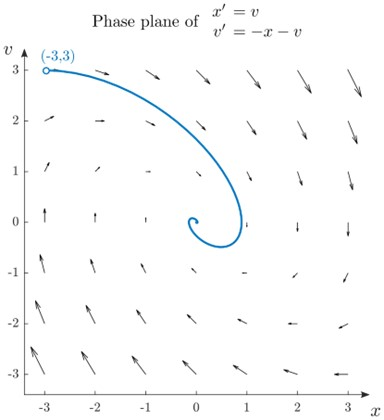

*Phase plane of the mass-spring-damper ODE system with *$m = k =c = 1$* and *$F = 0$*. The initial conditions are *$x(0) = -3$ and $v(0)$ = 3.

Typically, ODE solution curves are plotted against the time variable $t$. Solution curves plotted on the phase plane are different; they show how the solution evolves by plotting the dependent variables (often called the state variables) against each other. The plot of the solution in the phase plane can be correlated to the time series plots.

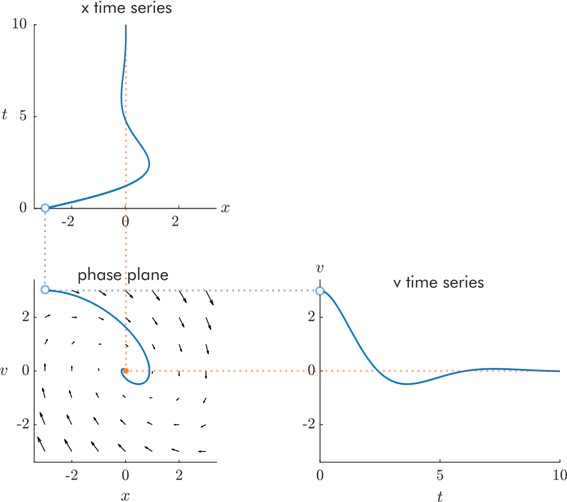    

*Time series plots of the solution curve plotted alongside the phase plane. Notice that the *$x$ *time series axes have been flipped so that they align with the phase plane.*

The time series solution plots are captured concisely in the phase plane plot:

- The initial value of each time series matches a coordinate of the initial point in the phase plane. 

- The time series plots approach a constant value. The phase plane solution converges to a single point that matches the long-term behavior of the time series.

   **Activity. **In this activity, you will use the Phase Plane app to analyze the solutions of the mass-spring-damper system in the phase plane.


$$\begin{array}{rl}

x' &= v
\\
v' &= \frac{1}{m}( F - kx - cv)
\end{array}$$


The mass-spring-damper system will exhibit different behaviors depending on the values of the parameters $m$, $F$, $k$, and $c$. 

**Part 1. Damped oscillations**

**Task 1.** Set the ODE system in the Phase Plane app to 


$$\begin{array}{rl}

x' &= v
\\
v' &= \frac{1}{m}( F - kx - cv)
\end{array}$$


and define the parameters $m = 1$, $F = 0$, $k = 1$, and $c = 1$. Also, set reasonable axes, e.g., $x: [-3,3]$, $v: [-3,3]$.

**Task 2. **Slow the animation speed down using the slider. Then, plot several solutions by clicking on the Phase Plane. Notice how the time series behavior matches up with the solution plotted on the phase plane.

**Task 3. **In the long-term behavior, all of the solutions approach one point. What point do they approach? Type your answer as a coordinate without the parentheses in the space provided below as a comma-separated list, e.g., 1, 2.

eqPoint = [0,0];
CheckMSDEq(eqPoint) % Checks your answer

Correct!


**  Reflect.** 

- How would you modify the system so that the equilibrium point is at $(3,0)$?

- Is it possible to modify the $v$ coordinate of the equilibrium point using the given parameters?

**Part 2. Undamped oscillations**

**Task 1.** Continue to analyze the mass-spring-damper ODE but set the damping $c = 0$.

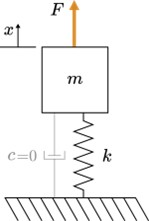

*With the damping set to zero, the system becomes an ideal mass-spring system.*

**Task 2. **Plot several solutions by clicking on the phase plane. Notice how the time series plot corresponds to the solution graphed on the phase plane. 

**Task 3. **What is the long-term behavior of solution curves in the phase plane? Solution curves

     **a.** spiral into an equilibrium point        **b.** diverge to infinity        **c.** cycle indefinitely          

yourAnswer = "c"; % Select an answer
CheckUndamped1(yourAnswer) % Checks your answer

Correct!


**Task 4.  **Set c = 0.001. What is the long-term behavior of solution curves in the phase plane? Solution curves

      **a.** spiral into an equilibrium point        **b.** diverge to infinity        **c.** cycle indefinitely      

yourAnswer = "a"; % Select an answer
CheckUndamped2(yourAnswer) % Checks your answer

Correct!


**Part 3. Overdamped system**

**Task 1.** Begin increasing the parameter $c$. At some point, the solution will become **overdamped**. In the overdamped system, there are no oscillations beyond the initial transient caused by the initial conditions. 

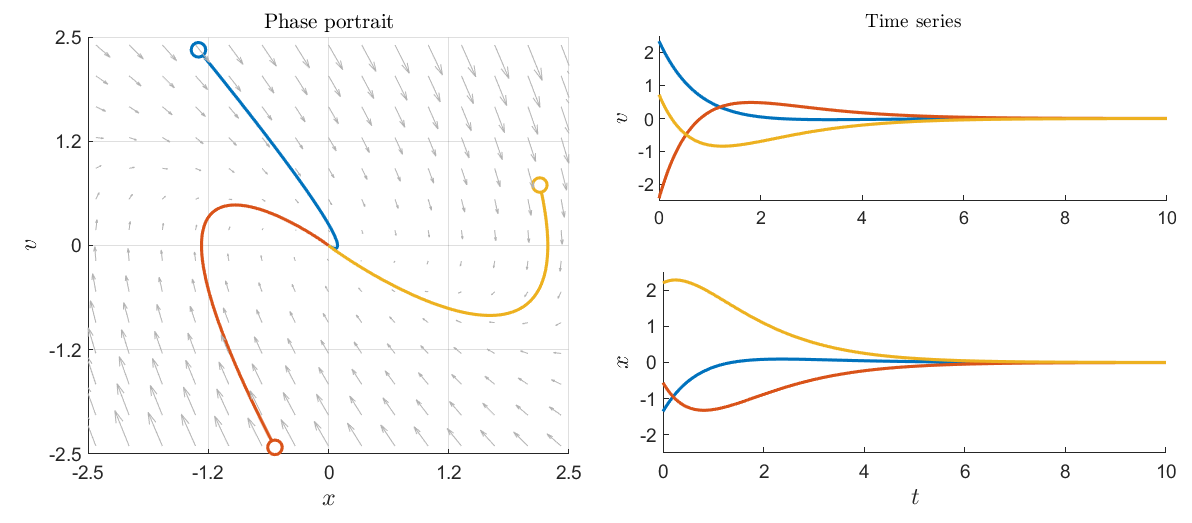

*Phase portrait of the critically damped mass-spring-damper system*

At what value of $c$ does the portrait transition from being damped to overdamped? Refer to the graph above to identify what the phase plane should look like at the transition point.

cvalue = [2];
CheckOverdamped(cvalue) % Checks your answer

Correct!


**Task 2. **Set the external force $F = 1$. What point do the solutions converge to? Type your answer as a coordinate without the parentheses in the space provided below as a comma-separated list, e.g., 1, 2.

eqPoint2 = [1,0];
CheckMSDEq2(eqPoint2) % Checks your answer

Correct!


**  Reflect.** 

- Physically, what causes the position coordinate ($x$) of the equilibrium to change when $F \neq 0$? Why does the velocity coordinate of the equilibrium remain zero?

- If $F = 1$ and $k$ is increased, how will the equilibrium point change?

- If $F = 1$ and $m$ is decreased, how will the equilibrium point change?

    **Activity. **In this activity, you will visualize the motion of the mass-spring-damper.

- Set the damping coefficient $c = 0.5$ to view the damped case.

- Set the damping coefficient $c = 0$ to view the undamped case.

- Set the damping coefficient $c = 2$ to view the critically damped case.

- Set the damping coefficient $c = 4$ to view the overdamped case.

- Set the external force $F = 1$ to view the change in equilibrium.

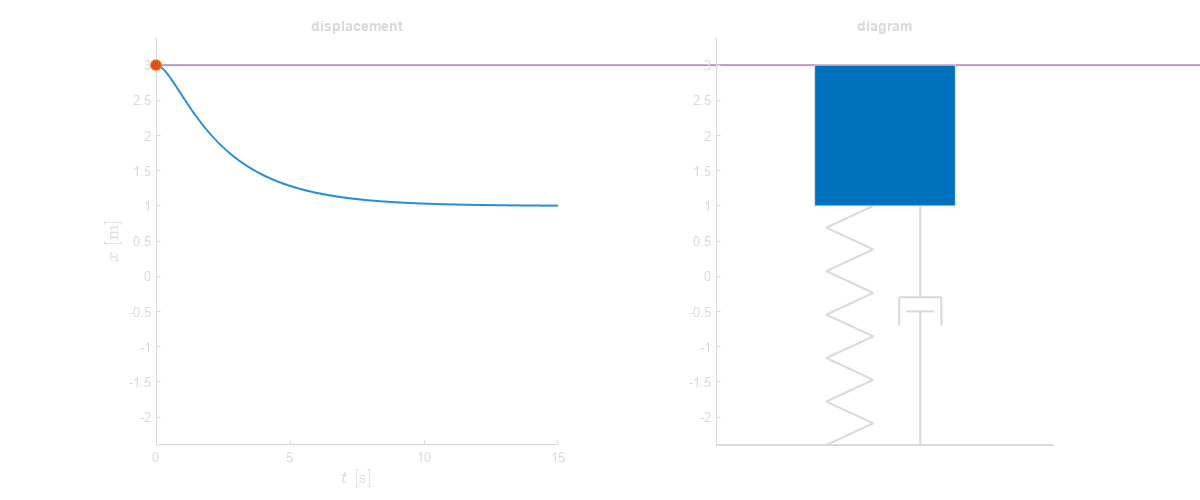

% Create solution array
tf = 15; % Simulation duration [s]
m = 1;   % mass [kg]
k = 1;   % spring stiffness [N/m]
c =2.75; % damping coefficient [Ns/m]
F =1; % externally applied force [N]
SolveAndAnimateMSD(m,F,k,c,tf) % This helper function solves and visualizes the system

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

**Display answers**

function ShowPendulumAnswer(showAnswer)
    if(showAnswer)
        syms theta omega t g l
        S1 = "omega";
        S2 = "-g/l*sin(theta)";

        symstr = ["'a. The system is'"; "'d*theta'/(d*t) == " + S1; ...
                  "d*omega/(d*t) == " + S2; "'b. The system is nonlinear.'"];
        displayFormula(symstr)
    end
end

**Checks**

function CheckCriterionExercise(equationList)
    IsEqualCheck([3 6],equationList)
end

function CheckMSDEq(eqPoint)
    IsEqualCheck([0 0],eqPoint)
end

function CheckUndamped1(yourAnswer)
    IsEqualCheck("c",yourAnswer)
end

function CheckUndamped2(yourAnswer)
    IsEqualCheck("a",yourAnswer)
end

function CheckOverdamped(cvalue)
    IsEqualCheck(abs(cvalue-2)<0.2,1)
end

function CheckMSDEq2(eqPoint2)
    IsEqualCheck([1 0],eqPoint2)
end

function IsEqualCheck(userSubmission,correctAnswer)
    % This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

**Visualizations**

function SolveAndAnimateMSD(m,F,k,c,tf)
    % Solve the ODE
    odeFunc = @(t,X) [X(2); (F - k*X(1) - c*X(2))/m];
    tlimits = 0:0.05:tf;
    [t,x] = ode45(odeFunc,tlimits,[3 0]);

    % Create the animation
    AnimateSingleMSD(t,x(:,1),2)
end

function AnimateSingleMSD(t,x,w)
% Generates an animation of a single mass/spring/damper
% t: time array
% x: displacement array
% w: width of the mass

    colors = lines(6); 
    fs = 14;
    
    % Create plot
    k = 1;
    f = figure("position",[0 0 1200 500]);
    
    % Setup the figure
    buffer = 1.2;
    xrange = max(x) - min(x);
    xmax = min(x) + xrange*buffer ;
    xmin = max(x) - xrange*buffer - w*1.5;
    tlim = [t(1) t(end)];
    axisLim1 = [tlim(1),tlim(2),xmin,xmax];
    axisLim2 = [-w*buffer,w*buffer,xmin,xmax];
    xground = xmin;
        
    sp1 = subplot(1,2,1);
    set(gca, "Clipping","off","Color","none"); 
    hold on
    plot(t,x,"-","LineWidth",1.5,SeriesIndex=1);
    a = plot([0, tlim(2)+(tlim(2)-tlim(1))*4], [x(k),x(k)],"-","color",[colors(4,:),0.5],"LineWidth",1.5);
    b = plot(t(k),x(k),"o","markerfacecolor",colors(2,:),"MarkerSize",8);
    hold off
    axis(axisLim1)
    box off
    xlabel("$t$ [s]","Interpreter","latex","FontSize",fs)
    ylabel("$x$ [m]","Interpreter","latex","FontSize",fs)
    title("displacement")
        
    sp2 = subplot(1,2,2);
    set(gca, "Clipping","off","Color","none");
    hold on
    plot([-w*buffer w*buffer],[xground xground],"LineWidth",1.5,SeriesIndex="none");
    
    % Plot mass
    x1 = x(k) - w/2;
    c = rectangle("Position",[-w/2 x1-w w w],"FaceColor",colors(1,:));
    
    % Plot spring
    xextension = x(k)-w;       
    xs = linspace(xground,xextension,12);
    ys = w/6*(-1).^(1:numel(xs)) - w/4;
    d = plot(ys,xs,"LineWidth",1.5,SeriesIndex="none");
    % Plot damper
    ydamp = w/4;

    xdamp1 = xground + (xextension-xground)/2 + w*0.1;
    xdamp2 = xground + (xextension-xground)/2;
    xdamp3 = xground + (xextension-xground)/2 + w*0.2;
    e = plot([ydamp,ydamp,NaN,ydamp-w/10,ydamp+w/10],[xground,xdamp1,NaN,xdamp1,xdamp1],"LineWidth",1.5,SeriesIndex="none");
    f = plot([ydamp-w*0.15,ydamp-w*0.15,NaN,ydamp+w*0.15,ydamp+w*0.15,NaN,ydamp-w*0.15,ydamp+w*0.15,NaN,ydamp,ydamp],...
        [xdamp2,xdamp3,NaN,xdamp2,xdamp3,NaN,xdamp3,xdamp3,NaN,xdamp3,xextension],"LineWidth",1.5,SeriesIndex="none");
    
    hold off
    axis equal
    axis(axisLim2)
    ax = gca;
    ax.XAxis.Visible = "off"; 
    title("diagram")

    % Create animation
    for k = 1:length(t)
        % displacement
        a.YData = [x(k),x(k)];
        b.XData = t(k);
        b.YData = x(k);
        % mass
        c.Position = [-w/2,x(k)-w,w,w];
        xextension = x(k)-w;       
        % spring
        d.YData = linspace(xground,xextension,12);
        % damper
        xdamp1 = xground + (xextension-xground)/2 + w*0.1;
        xdamp2 = xground + (xextension-xground)/2;
        xdamp3 = xground + (xextension-xground)/2 + w*0.2;
        e.YData = [xground xdamp1 NaN xdamp1 xdamp1];
        f.YData = [xdamp2 xdamp3 NaN xdamp2 xdamp3 NaN xdamp3 xdamp3 NaN xdamp3 xextension]; 
        pause(0)
    end

end
